clear all
clf
% first manually delete tab References
v = 'valentia.xlsx';

s = readtable (v); % reading data from the specific Data File

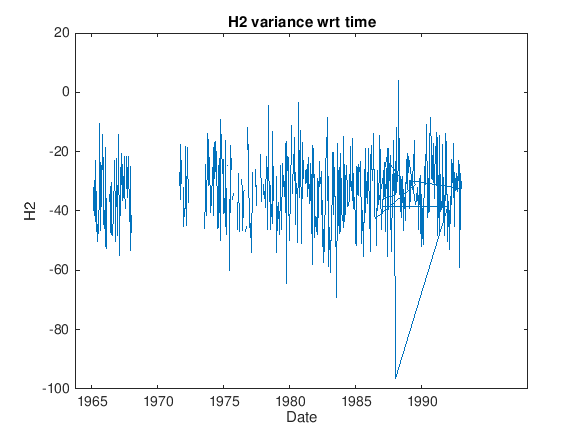

d = datenum(s.Date, 'yyyy-mm-dd'); % converting date to machine readable serial code

% convenient labelling of variables
H3 = s.H3;
H2 = s. H2;
O18 = s.O18;

figure (1)
plot (d, H2)
% make x-axis more human-readable
xticks (712224:3650:735965);
xticklabels(1960:5:2015);
xlabel ('Date');
ylabel ('H2');
title ('H2 variance wrt time')

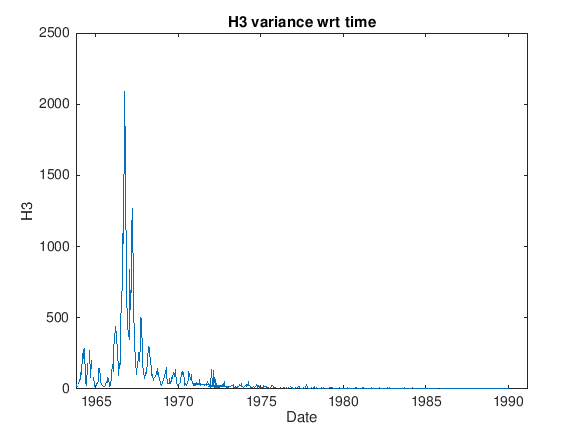


figure (2)
plot (d, H3);
% make x-axis more human-readable
xticks (712224:3650:735965);
xticklabels(1960:5:2015);
xlabel ('Date');
ylabel ('H3');
title ('H3 variance wrt time')

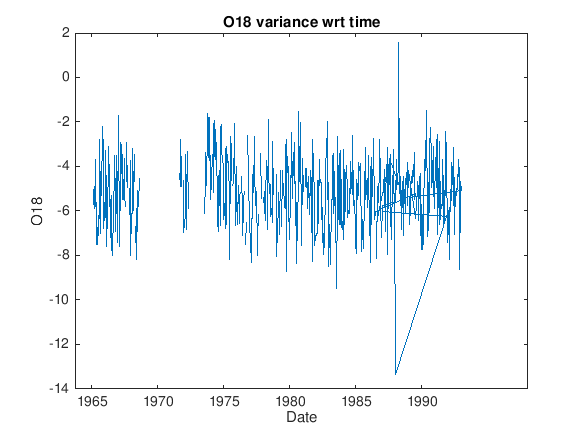


figure (3)
plot (d, O18);
% make x-axis more human-readable
xticks (712224:3650:735965);
xticklabels(1960:5:2015);
xlabel ('Date');
ylabel ('O18');
title ('O18 variance wrt time')

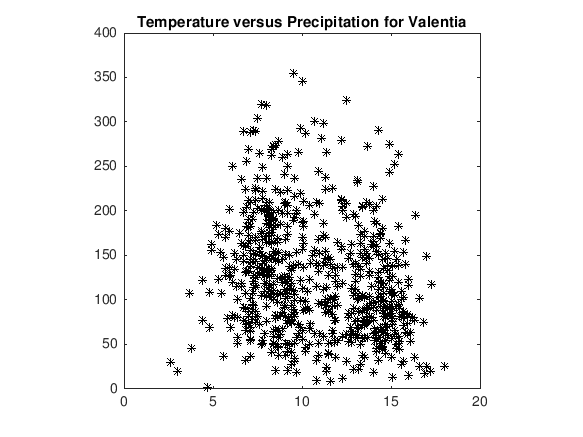

% Investigating temperature dependence of precipitation (scatter plot) for Valentia data

precip = s.Precipitation;
temp = s.AirTemperature;

figure(4)
scatter (temp, precip, '*k')
axis square
box on
title ('Temperature versus Precipitation for Valentia')